# SC42025 Filtering & Identification

**PRACTICAL ASSIGNMENT II**

**Instructions: Fill in the live script with your code and answers. Then export the live script as a pdf (in the 'Live Editor tab', click on the arrow under 'Save' and then 'Export to pdf'). Hand in one report per group before the deadline.**

**DEADLINE**: 

## Introduction

In this practical assignment you will use your model-estimation code from Homework Assignments 3 & 4  to identify an unknown system by going through the system identification cycle. For this, you need the file `exciteSystem.p`, which you can find on Brightspace. Note that this file requires the `System Identification Toolbox. `You may consider this file as an **unknown black box system**. You can provide an input sequence and a sampling frequency to this system and it will return a corresponding output sequence at the specified sampling frequency.

The file is used by adding it to your path in MATLAB and calling the function

`y = exciteSystem(STUDENTID,u,fs)`

Here, `y` is the output sequence $$y_k$$ of the to be identified system, `STUDENTID` is the **lowest-valued** student-id of the students in the group, `u` is the provided input sequence $u_k$, and` fs` is the sampling frequency. 

The system is inherently simulated in discrete time, so there is **no need for you to apply a band-pass filter to prevent anti-aliasing**, as you need to do for analog systems that have been sampled digitally. Your objective is to identify a model for this black box system. Try to determine a model that performs well on both your identification as your validation data set in terms of simulation.

It can be expected that non-Gaussian sensor noise (noise spikes) will be present in the output. These spikes need to be removed from the data before identifying the system. 

Your system may also contain a time delay. This should also be taken into account before using your identification code.

To complete this assignment, we expect you to go trough the identification cycle, see the figure below, as many times as needed.

*Throughout this practical assignment, remember that the identification cycle is an iterative process and you typically need more than one iteration. Limit your report to the final iteration.*

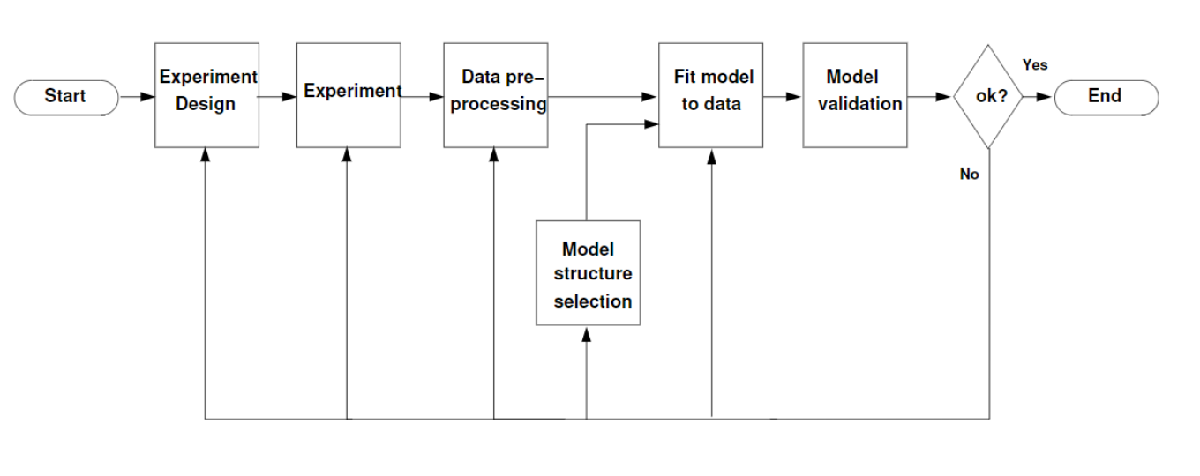

## Part 0: Setup

Please insert your names and student numbers below.

Name: Josephine King

Student Number: 6250513

Name: Thomas Prins 

Student Number: 5885221

% Clear workspace
clearvars; clc; close all;

% Insert the lowest-valued student-id of the students in the group;
STUDENTID = 5885221;

## Part 1: Experiment Design and Data Pre-Processing

The first steps of the identification cycle are to design your experiment and pre-process the input and output data. In this exercise, use the `exciteSystem` function to determine a suitable sampling frequency and motivate your answer.

*Answer**:*

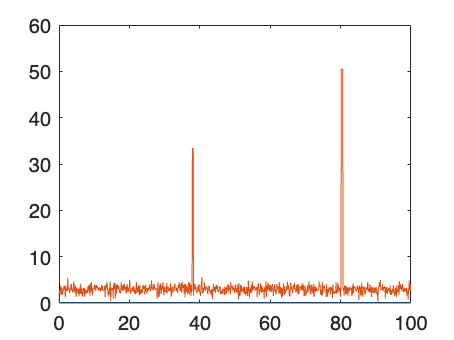

N = 1000;
fs_init = 10;
t = 0:1/fs_init:((N-1)/fs_init);
u = zeros(1,N);
u(1) = 1;

% Choose a very high frequency to analyze the frequency response
y = exciteSystem(STUDENTID,u,fs_init);

figure(1)
plot(t,u,t,y)

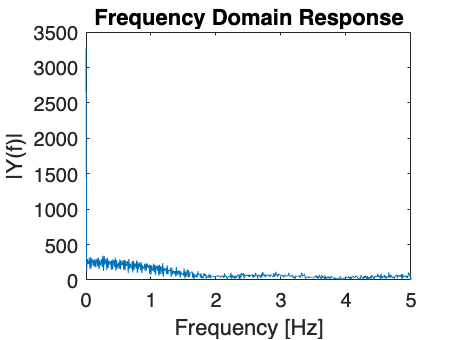


Y = fft(y); 
f = (0:N-1)*(fs_init/N);  
magnitude = abs(Y); 

figure(2)
plot(f, magnitude); 
xlabel('Frequency [Hz]');
ylabel('|Y(f)|');
title('Frequency Domain Response');
xlim([0 fs_init/2]); 

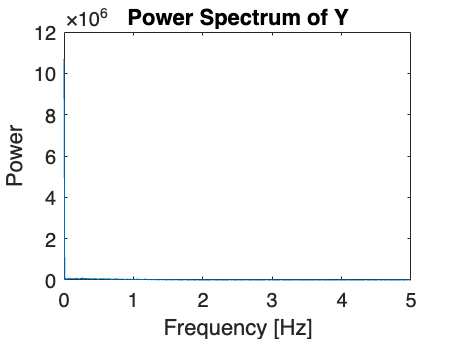


figure(3)
Pyy = abs(fft(y)).^2;  
plot(f, Pyy(1:N));
xlabel('Frequency [Hz]');
ylabel('Power');
title('Power Spectrum of Y');
xlim([0 fs_init/2]);


fs = 1.36*2;

Design a persistingly exciting input signal. Show how you determined the order of persistency of excitation.  Furthermore, you are **not allowed** to use a white-noise sequence as an input signal, as this is often not possible in the real-world.

*Answer**:*

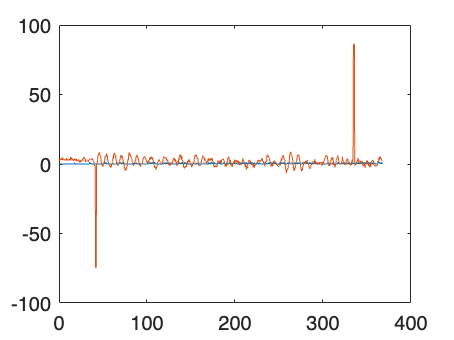

% Use MATLAB's chirp function to create a frequency sweep
t = 0:1/fs:((N-1)/fs);
u = prbs(50,N);
y = exciteSystem(STUDENTID,u,fs);
figure(1)
plot(t,u,t,y)

Motivate how you identify and remove spike noise from your data.*You may use the Matlab function *`interp1`* to do the interpolation. *Plot a figure of the output signal before and after spike removal.

*Answer**:*

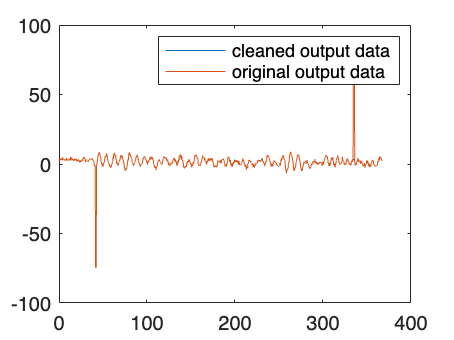

corrupted = find(abs(y) > 20);
x = 1:length(y);
y_clean = y;

y_clean(corrupted) = NaN;
cleaned_vals = interp1(x(~isnan(y_clean)), y_clean(~isnan(y_clean)), corrupted, 'pchip');
y_clean(corrupted) = cleaned_vals;

figure(1)
plot(t,y_clean,t,y)
legend("cleaned output data", "original output data")


y = y_clean;

Determine any time-delays of your system. Correct the input and output data to account for the determined time-delay by introducing an appropriate time-shift.

*Answer**:*

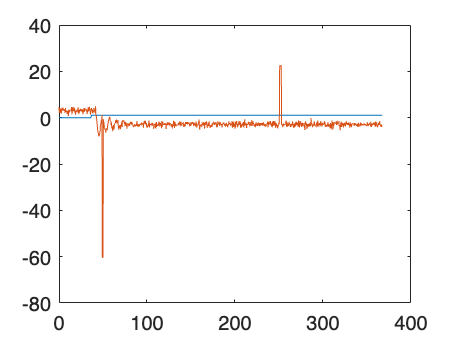

u_step = ones(1,N);
u_step(1:N/10) = 0;

t = 0:1/fs:((N-1)/fs);

% Choose a very high frequency to analyze the frequency response
y_step = exciteSystem(STUDENTID,u_step,fs);

plot(t,u_step,t,y_step)

Remove the DC offset from the output (if any).

*Answer**:*

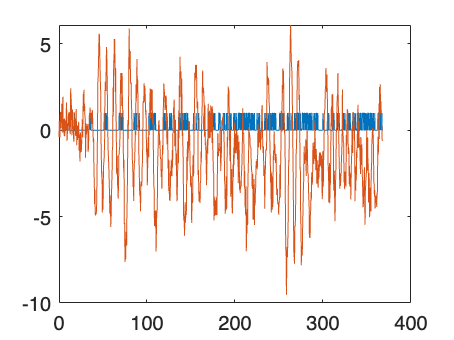

u_dc = zeros(1,N);
y_dc = exciteSystem(STUDENTID,u_dc,fs);

dc_offset = mean(y_dc);
y = y - dc_offset;
figure(1)
plot(t,u,t,y)

Determine whether your system is (approximately) linear by means of an experiment. Plot a figure of the experiment that you used and use this figure to motivate your conclusions.

*Answer**:*

%YOUR CODE HERE

Generate output data that you will use for identification using your persistently exciting input signal. Also generate new data that you will use for validation.

*Answer**:*

start_val = round(0.8*N);
uTrain = u(1:start_val-1);
yTrain = y(1:start_val-1);
uVal = u(start_val:end);
yVal = y(start_val:end);

## Part 2: Identification

You will now identify your system using the data that you generated in Part 1. Here, we highly recommend you to use your code from Homework Assignments 3 & 4. It is however **not allowed** to use tools from the `System Identification Toolbox` to identify your system.

Determine the model order. Plot the singular values using the `semilogy` command and motivate your choice of order.

*Answer**:*

%YOUR CODE HERE

Identify the model. You are free to choose the identification method.

*Answer**:*

%YOUR CODE HERE

## Part 3: Validation

The final step of the system identification cycle is to validate your model. In this part you will validate your identified model using validation data that was **not** used during identification. 

Compare and discuss the VAF for the identification data with the VAF for the validation data.

*Answer**:*

%YOUR CODE HERE

Determine and discuss the auto-correlation of the residuals.

*Answer**:*

%YOUR CODE HERE

Determine and discuss the cross-correlation between the residuals and the inputs.

*Answer**:*

%YOUR CODE HERE

**Is your model OK? If not, return to Part 1 and Part 2 for the next iteration. **

## Functions

Implement your functions in this section

### Prediction Error Methods

Implement your PEM functions below 

%YOUR CODE HERE

### Subspace ID Methods

Implement your Subspace ID functions below 

%YOUR CODE HERE